# Automated Parking Valet with ROS 2 in Simulink

This example shows how to distribute the Automated Parking Valet application among various nodes in a ROS 2 network in Simulink® and deploy them as standalone ROS 2 nodes. This example extends the [Automated Parking Valet in Simulink](docid:driving_ug.mw_a648d83c-5fe4-4459-9978-5e4d0ea396e5) example in the Automated Driving Toolbox™. Using the Simulink model in the Automated Parking Valet in Simulink example, tune the planner, controller and vehicle dynamic parameters before partitioning the model into ROS 2 nodes.

Prerequisites: [Automated Parking Valet in Simulink](docid:driving_ug.mw_a648d83c-5fe4-4459-9978-5e4d0ea396e5), [Generate a Standalone ROS 2 Node from Simulink](docid:ros_ug.mw_9b7b0ac7-5df9-47f0-bf5f-1920db61f3f7)

## Introduction

This autonomous vehicle application has the following components.

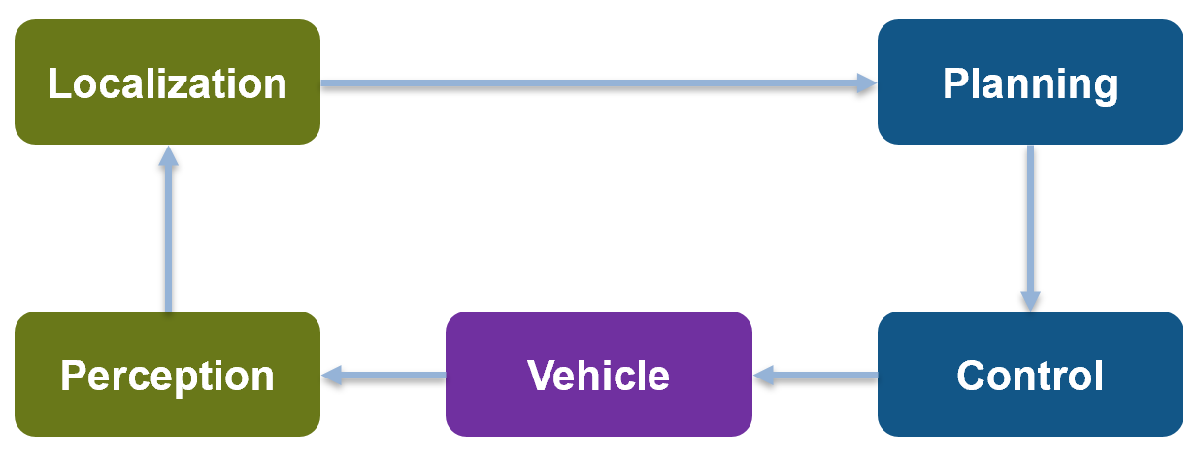

This example concentrates on simulating the *Planning*, *Control *and the *Vehicle *components. For *Localization*, this example uses pre-recorded localization map data. The *Planning *component is further divided into *Behavior planner *and *Path Planner* components. This results in a ROS 2 network comprised of four ROS 2 nodes: `Behavioral Planner`*,* `Path Planner`, `Controller` and `Vehicle`. The following figure shows the relationships between each ROS 2 node in the network and the topics used in each.

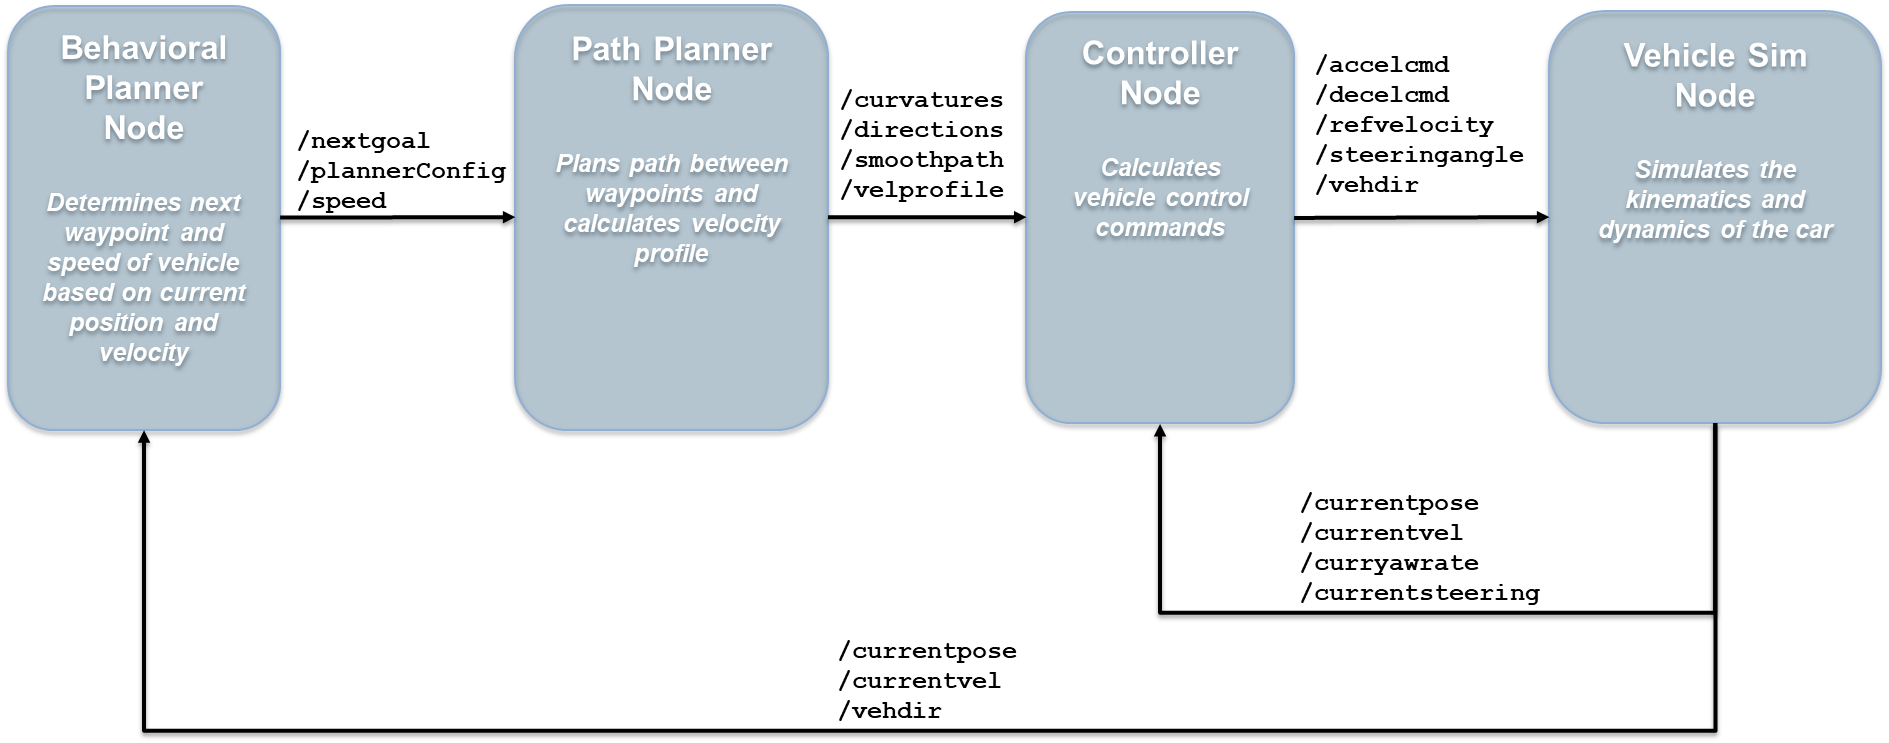

## Explore the Simulink ROS 2 nodes and connectivity

Observe the division of the components into four separate Simulink models. Each Simulink model represents a ROS 2 node.

### Vehicle Node

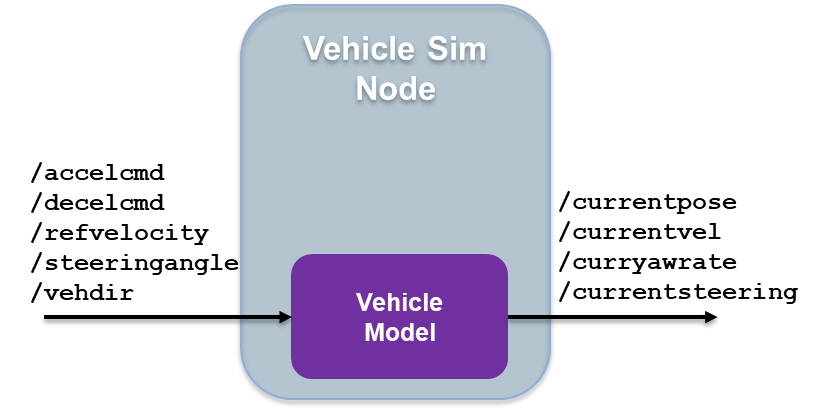

    1. Open the vehicle model.

open_system('ROS2ValetVehicleExample');

    2. The `Subscribe` subsystem contains the ROS 2 [Subscribe](docid:ros_ref.mw_cfb34e9a-c128-42eb-9b24-f92f6eab1b15) blocks that read input data from the Controller node.

  3. The `Vehicle model` subsystem contains a [Bicycle Model](docid:driving_ref.mw_9569b0a8-23c5-4aaf-ba41-e3ebe9ef7971) block, `Vehicle Body 3DOF`*, *to simulate the vehicle controller effects and sends the vehicle information over the ROS 2 network through ROS 2 [Publish](docid:ros_ref.mw_4cb02692-145a-4e26-8279-6532cd5d81f5) blocks in the `Publish` subsystem.

### Behavioral Planner Node

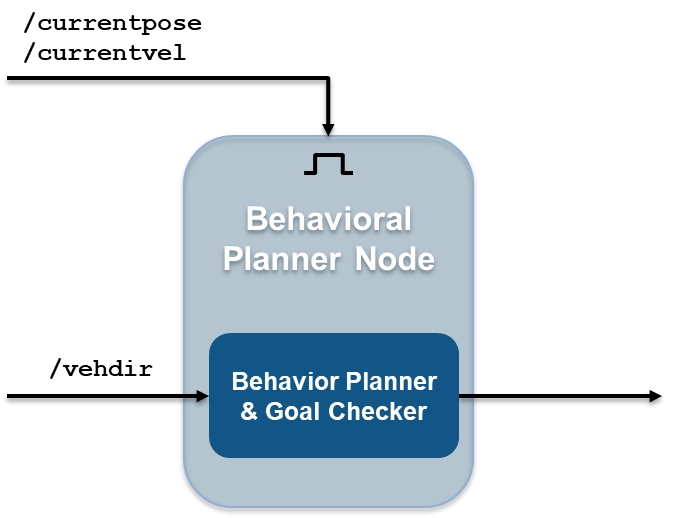

    1. Open the behavioral planner model.

open_system('ROS2ValetBehavioralPlannerExample');

    2. This model reads the current vehicle information from ROS 2 network, sends the next goal and checks if the vehicle has reached the final pose of the segment using `rosAutomatedValetHelperGoalChecker`.

    3. The `Behavioral` `Planner` `and` `Goal` `Checker` subsystem runs when a new message is available on either `/currentvel` or `/currentpose`.

    4. The model sends the status if the vehicle has reached the final parking goal using the `/reachgoal` topic, which uses a `std_msgs/Bool` message type. All the models stop simulation when this message is `true`.

### Path Planner Node

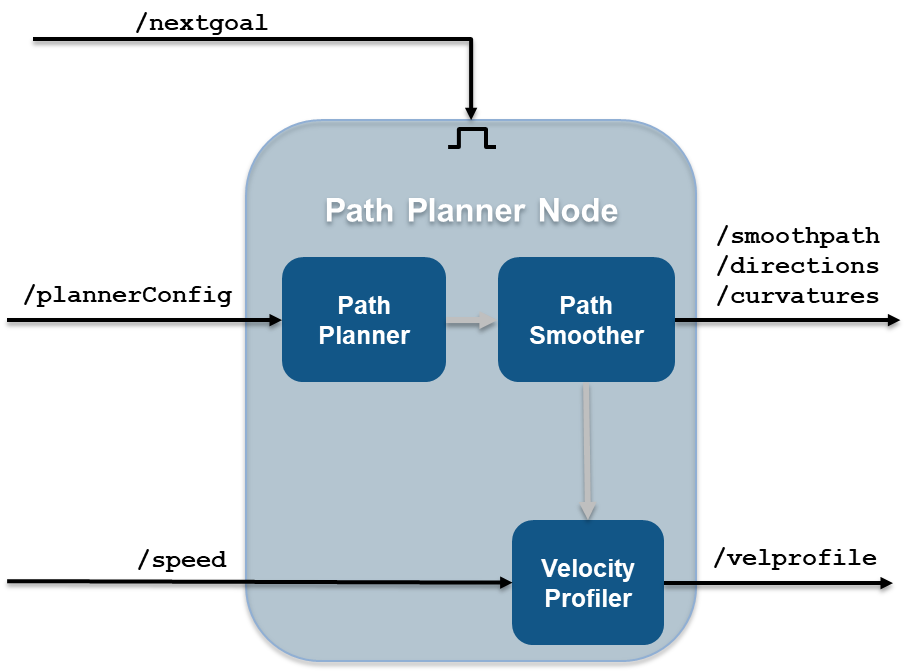

    1. Open the path planner model.

open_system('ROS2ValetPathPlannerExample');

    2. This model plans a feasible path through the environment map using a [`pathPlannerRRT`](docid:driving_ref.mw_3e6efb93-e83e-4c4b-9e7b-0bebb1c1179c) object, which implements the *optimal rapidly exploring random tree* (RRT*) algorithm and sends the plan to the controller over the ROS 2 network.

    3. The `Path Planner` subsystem runs when a new message is available on `/plannerConfig` or `/nextgoal` topics.

### Controller Node

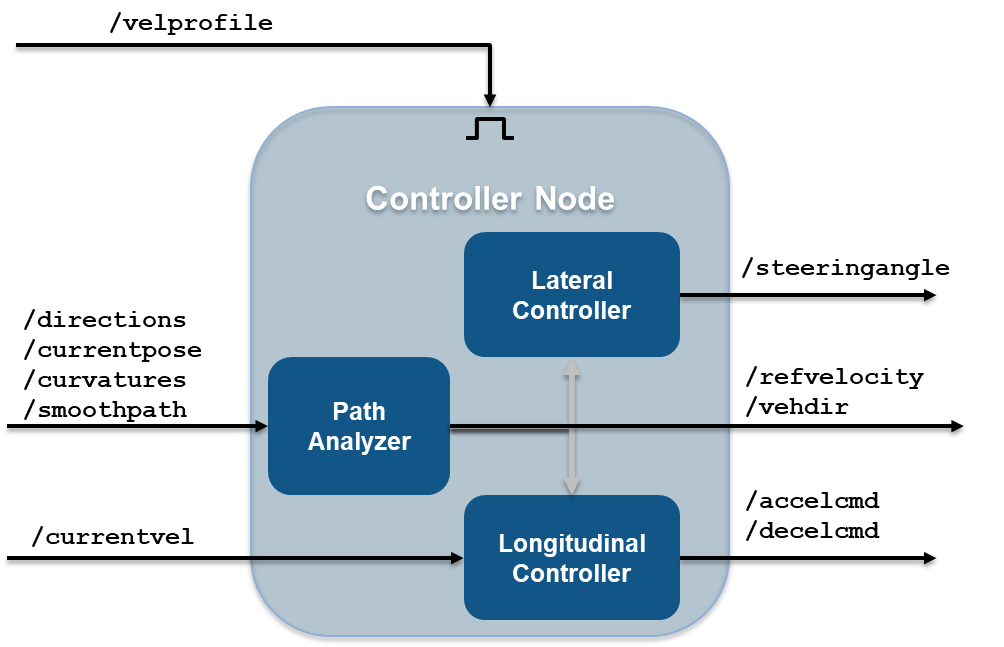

    1. Open the vehicle controller model.

open_system('ROS2ValetControllerExample');

    2. This model calculates and sends the steering and velocity commands over the ROS 2 network.

    3. The Controller subsystem runs when a new message is available on the `/velprofile` topic.

## Simulate the ROS 2 nodes to verify partitioning

Verify that the behavior of the model remains the same after partitioning the system into four ROS 2 nodes. 

    1. Load the pre-recorded localization map data in MATLAB base workspace using the `exampleHelperROSValetLoadLocalizationData` helper function.

exampleHelperROSValetLoadLocalizationData;

    2. Open the simulation model.

open_system('ROS2ValetSimulationExample.slx');

    In the left parking selection area, you can also select a spot. The default parking spot is the sixth spot at the top row.

    3. In the SIMULATION tab, click **Run** from **SIMULATE** section or run `sim('ROS2ValetSimulationExample.slx')` in MATLAB Command Window. A figure opens and shows how the vehicle tracks the reference path. The blue line represents the reference path while the red line is the actual path traveled by the vehicle. Simulation for all the models stop when the vehicle reaches the final parking spot.

sim('ROS2ValetSimulationExample.slx');

Unable to create mex function 'ROS2ValetPathPlannerExample_sfun.mexw64' required for simulation.

### Simulation Results

The `Visualization` subsystem in vehicle model generates the results for this example.

open_system('ROS2ValetVehicleExample/Vehicle model/Visualization');

The v`isualizePath` block is responsible for creating and updating the plot of the vehicle paths shown previously. The vehicle speed and steering commands are displayed in a scope.

open_system("ROS2ValetVehicleExample/Vehicle model/Visualization/Commands")

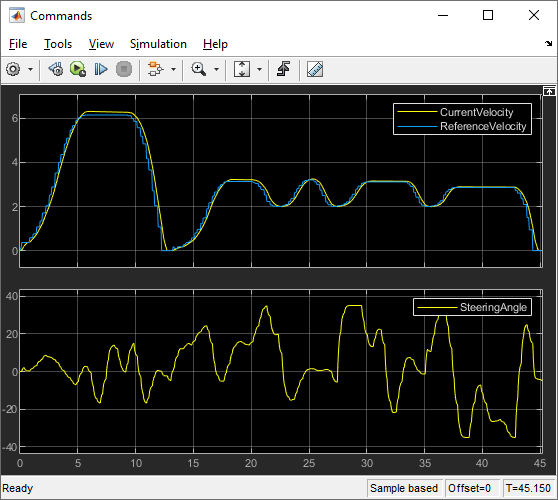

## Deploy ROS 2 Nodes

Generate ROS 2 applications for `Behavioral Planner`, `Path planner` and `Controller` nodes. Simulate the `Vehicle` node in MATLAB and compare the results with simulation.

Generate and deploy `Behavioral Planner`, `Path Planner` and `Controller` node applications using `exampleHelperROS2ValetDeployNodes` helper function. The helper function calls [`slbuild`](docid:simulink_ref.btvn60i) command with the name of the Simulink model as input argument, for each model, to generate C++ code and deploy the application on the host computer.

exampleHelperROS2ValetDeployNodes(); % generate C++ code and deploy the application for ROS 2 nodes

Open the vehicle model and start simulation.

open_system("ROS2ValetVehicleExample"); 
set_param("ROS2ValetVehicleExample","SimulationCommand","start"); 

Verify that the results from simulation match with the deployed ROS 2 nodes.

*Copyright 2019-2020 The MathWorks, Inc.*